# The Central Limit Theorem

The Central Limit Theorem is the mainstay of data analysis. The percursor to this theorem is the Law of Large Numbers. Let's investigate this for data sampled from a normal distribution. In this simulation we imagine that we are measuring a variable in an experiment and that the variable is distributed according to a normal distirbution with a set mean and standard deviation. We know that when we take only a small number of replicates of the measurement tha we will get a poor estimate of the real value of that variable. So here we will investigate how many replicates we need to get a good estimate of the mean of the value. We may also be interested in the standard devaiation of the original distribution and so we will investigate that as well. 

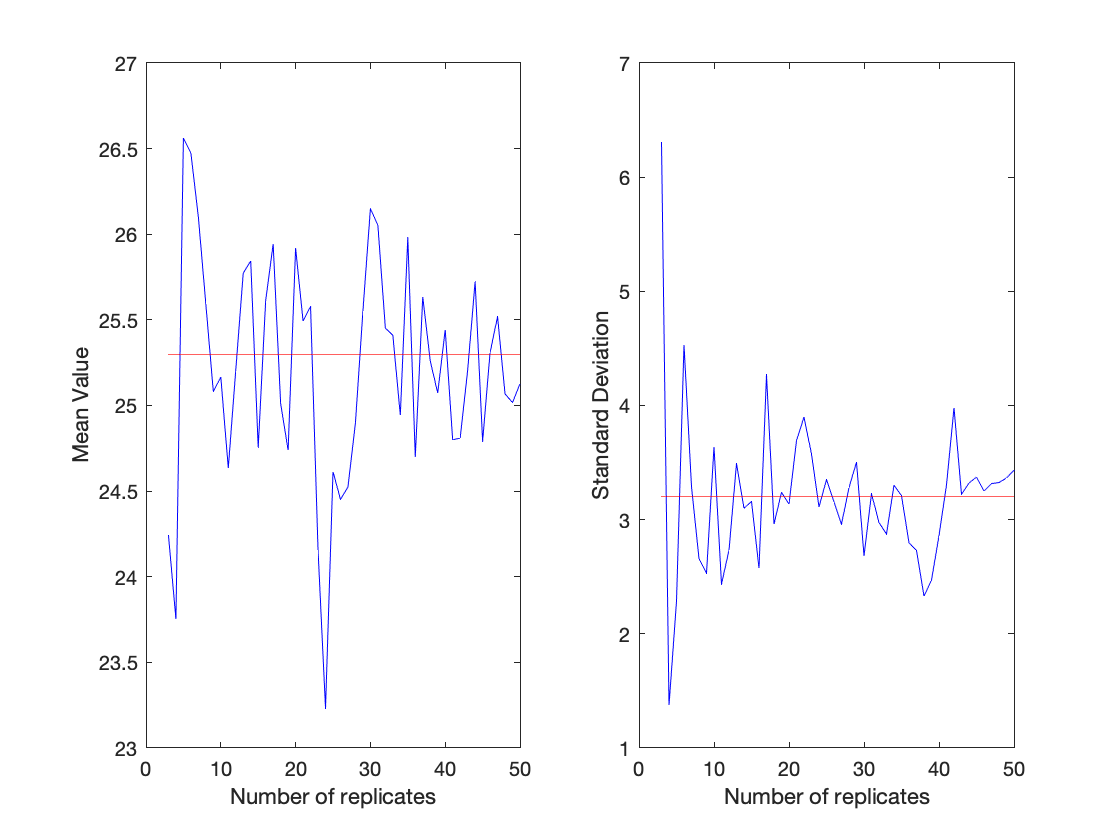

% Specify the mean and standard deviation of the normal distribution
mean_value = 25.3;
std_dev    = 3.2;

% Generate single samples of different numbers of replicates and calculate
% their means and standard deviations
n_replicates = 3 : 50;

expt_means = zeros(length(n_replicates),1);
expt_std   = zeros(length(n_replicates),1);

for i_expt = 1 : length(n_replicates)
    
    data = mean_value + std_dev*randn([n_replicates(i_expt),1]);
    
    expt_means(i_expt) = mean(data);
    expt_std(i_expt)   = std(data);
end

figure(1)
subplot(1,2,1)
plot(n_replicates, expt_means, 'b-', n_replicates, mean_value*ones(size(n_replicates)), 'r-')
xlabel('Number of replicates')
ylabel('Mean Value')

subplot(1,2,2)
plot(n_replicates, expt_std, 'b-', n_replicates, std_dev*ones(size(n_replicates)), 'r-')
xlabel('Number of replicates')
ylabel('Standard Deviation')

We can see from this that there is a lot of scatter about the actual mean and standard deviation values, and the difference from the actual values can be quite large. However, as we take more and more replicates, our estimates of the mean and standard deviation of the original distribution become better. 

***Exercise:**** Change the values of the mean and standard deviation and investigate how many replicates are needed for the mean and standard deviation from the experiments to agree well with the actual values (note that you will have to specify how good that agreement should be). *

The above simulation does not really test the Central Limit Theorem. To do that, we need to look at the distribution of means and standard deviations derived from many different experiments using the same number of replicates. We will look at this in the simluation that follows where we specifiy a reasonably small number of replicates, but we repeat that experiment with 5 replicates 1000 times. We can then plot a histogram of the means from each of these 1000 experiments and calculate the mean of that distribution. 

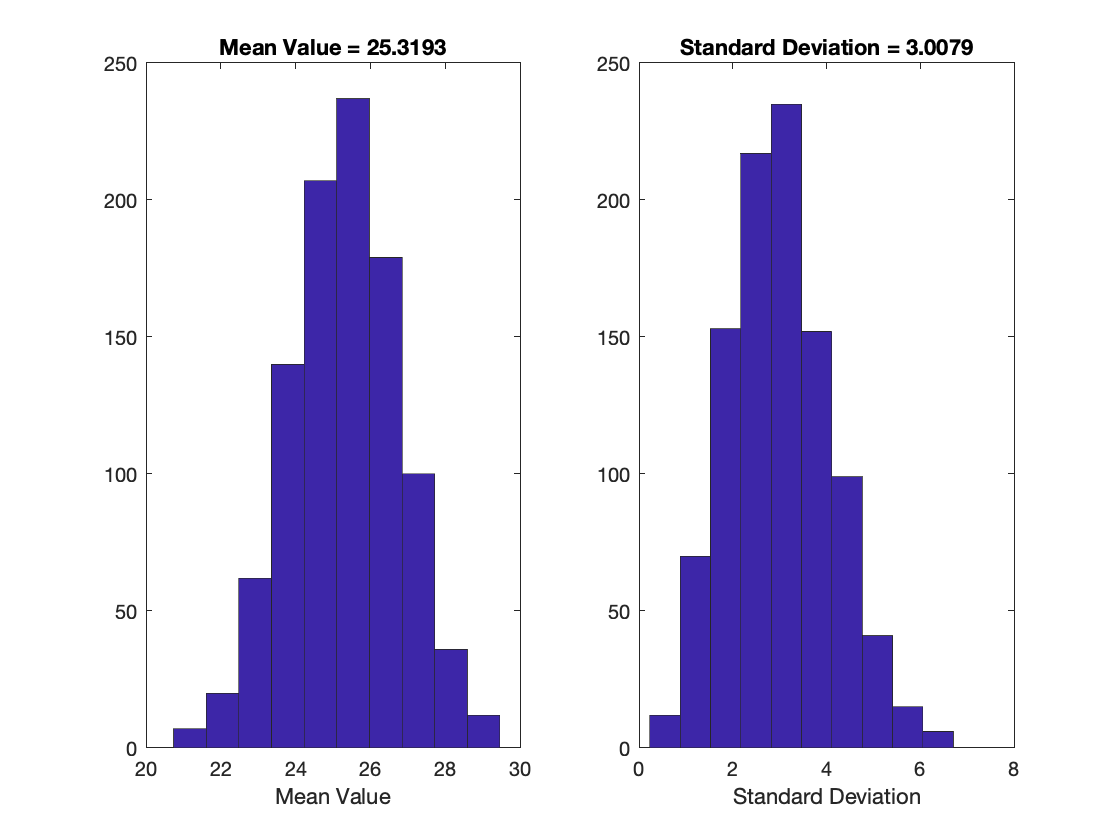

% Specifiy the number experiments.
n_expts      = 1000;
n_replicates = 5;

expt_means = zeros(n_expts, 1);
expt_std   = zeros(n_expts, 1);

for i_expt = 1 : n_expts
    
    data = mean_value + std_dev*randn([n_replicates,1]);
    
    expt_means(i_expt) = mean(data);
    expt_std(i_expt) = std(data);
       
end

figure(2)
subplot(1,2,1)
hist(expt_means)
xlabel('Mean Value')
title(['Mean Value = ' num2str(mean(expt_means))])

subplot(1,2,2)
hist(expt_std)
xlabel('Standard Deviation')
title(['Standard Deviation = ' num2str(mean(expt_std))])

We can see that this gives a very close value for the mean of the original distribution. The standard deviation is close, but not quite as accurate as the mean value. 

***Exercise:**** Investigate the accuracy of the mean and standard deviation as you change the number of replicates and the number of experiments separately.*

***Exercise:**** Keeping the number of replicates and experiments constant, vary the mean and standard deviation of the original distribution and see how this affects the accuracy of the mean and standard deviation obtained from the experiments. *

These results may not be too surprising because we have started with a normal distribtion. The power of the Central Limit Theorem lies in the fact that it applies for almost any original distribution. In what follow we will repeat the simulation but use a Poisson distribution as our original. The distirbution of mean values from all the experiments will approximate a normal distirbution whose mean value is very close to the mean of the original distribution. 

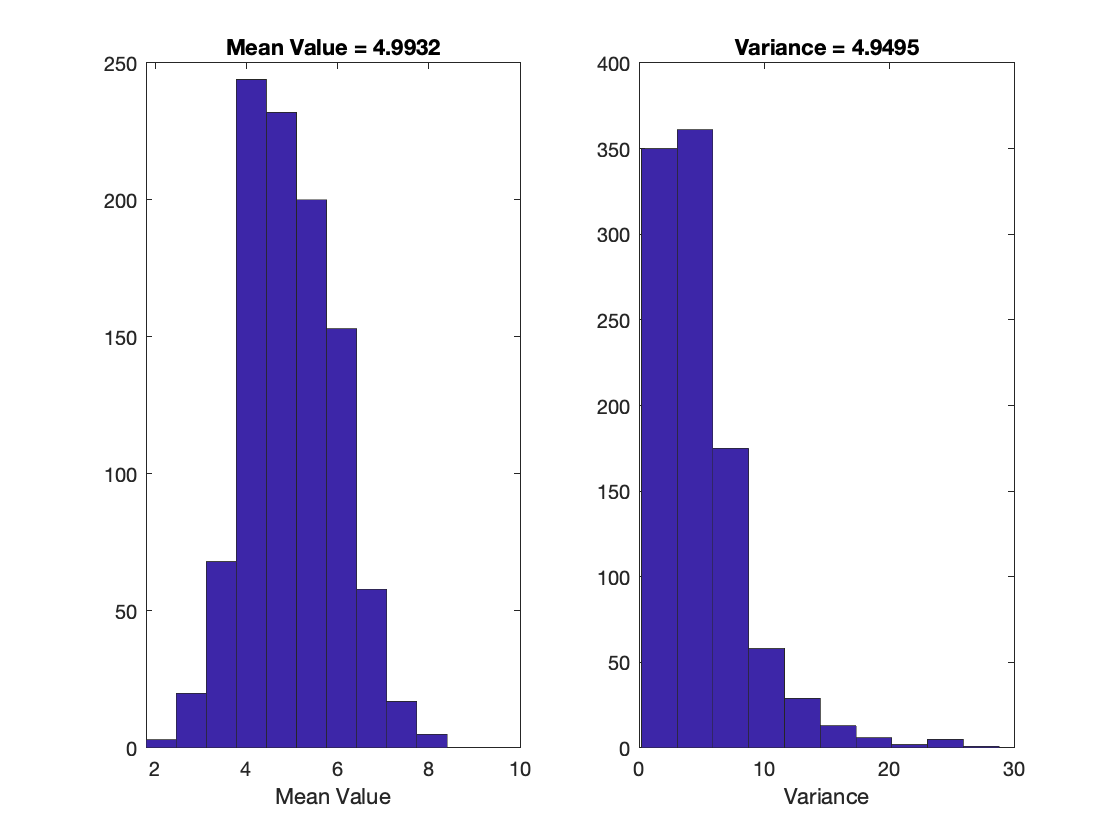

% Specify the mean of the Poisson distribution
lambda_p = 5.0;

% Specifiy the number experiments.
n_expts      = 1000;
n_replicates = 5;

expt_means = zeros(n_expts, 1);
expt_std   = zeros(n_expts, 1);

for i_expt = 1 : n_expts
    
    data = PoissonRNGMMEES(lambda_p, n_replicates);
    
    expt_means(i_expt) = mean(data);
    expt_std(i_expt) = std(data);
       
end

figure(3)
subplot(1,2,1)
hist(expt_means)
xlabel('Mean Value')
title(['Mean Value = ' num2str(mean(expt_means))])

subplot(1,2,2)
hist(expt_std.^2)
xlabel('Variance')
title(['Variance = ' num2str(mean(expt_std.^2))])

This may seem great in that it means effectively that we do not need to worry about the shape of the original distribution — the mean and variance of our experiment will be close to those of the original distribution. However, there is a problem. If the origianl distirbution has what is called a fat-tail, then the whole process breaks down (because the assumptions used in proving the theorem no longer hold). As an example of this we will look at the case of the Cauchy distribution. 

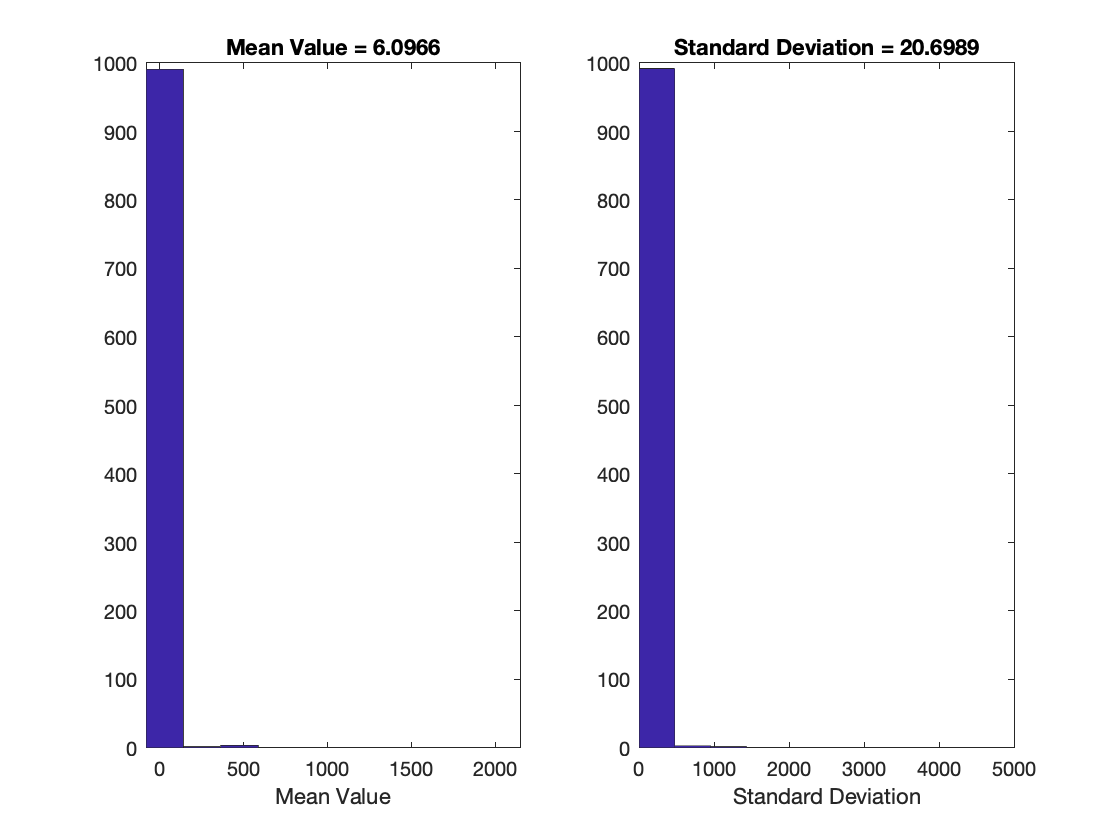

% Specify the parameters of the Cuachy Distribution
a = 0.0;
b = 1.0;

% Specifiy the number experiments.
n_expts      = 1000;
n_replicates = 5;

expt_means = zeros(n_expts, 1);
expt_std   = zeros(n_expts, 1);

for i_expt = 1 : n_expts
    
    data = CauchyRNGMMEES(a, b, n_replicates);
    
    expt_means(i_expt) = mean(data);
    expt_std(i_expt) = std(data);
       
end

figure(4)
subplot(1,2,1)
hist(expt_means)
xlabel('Mean Value')
title(['Mean Value = ' num2str(mean(expt_means))])

subplot(1,2,2)
hist(expt_std)
xlabel('Standard Deviation')
title(['Standard Deviation = ' num2str(mean(expt_std))])

Here we see that first of all the distribution of experiment mean values looks nothing like a normal distribution. Also, the mean of that distribution is not close to the actuall median. The reason for this is that the Cauchy distribution does not have a defined mean or variance because of the existence of fat tails. These fat tails mean that the distribution does not drop to zero at $\pm \infty$as fast as the normal distribution does, and so its mean is infinite. The moral of the story is that the Central Limit Theorem is a wonderful thing, but we need to be sure that the conditions under which is satisfied actually hold. 